Lista 05 - Projetos de Controladores na Frequência

Aluno: Vitor Augusto Tibério - 14658834 - Eng. Elétrica - EESC/SUP

Prof. Dr. Marcos Rogério Fernandes

## Atividade 01 

# SEL0459 - Controle Digital - SEL/EESC/USP

### Lista 05 - Projeto de controladores na frequencia - Parte 1

#### Prof. Dr. Marcos Rogério Fernandes

**Aluno:** Vitor Augusto Tibério - 14658834

Definindo a função de transferência:

numz = [0.0912 -0.0012 -0.0544 0];
denz = [1 -2.655 2.679 -1.391 0.3679];
Ts = 0.5;
Gf = tf(numz, denz, Ts);

Respota ao degrau:

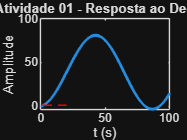

td=0:Ts:100; %vetor de tempo discreto
y1=step(Gf,td); %respota ao degrau
figure(1)
stairs(td,y1,'LineWidth',2);
title('Atividade 01 - Resposta ao Degrau')
xlabel('t (s)')
ylabel('Amplitude')
hold on
line([0 20],[1 1],'linestyle','--','color','red')

Respota a rampa:

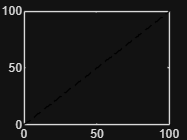

figure(2)
r=td'; %sinal de entrada (rampa)
stairs(td,td,'k--')

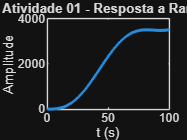

y_ramp=lsim(Gf,r,td); %simula entrada de sinal rampa
stairs(td,y_ramp,'LineWidth',2)
title('Atividade 01 - Resposta a Rampa')
xlabel('t (s)')
ylabel('Amplitude')

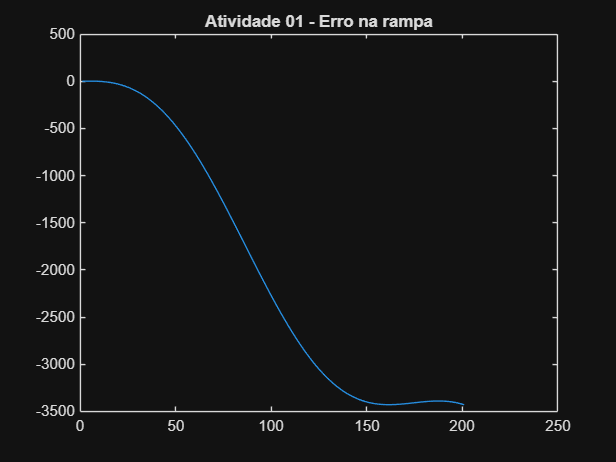

figure(3)
plot(r-y_ramp) %mostra sinal de erro (desvio de controle)
title('Atividade 01 - Erro na rampa')

Resposta a parábola:

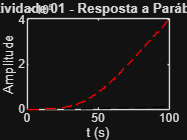

figure(4)
r=td.*td; %sinal parabola
r=r'; %transposto para tornar vetor coluna
plot(td,td.^2,'k--')
hold on
y_parab=lsim(Gf,r,td); %simula sinal de entrada tipo parabola
stairs(td,y_parab,'--r')
title('Atividade 01 - Resposta a Parábola')
xlabel('t (s)')
ylabel('Amplitude')

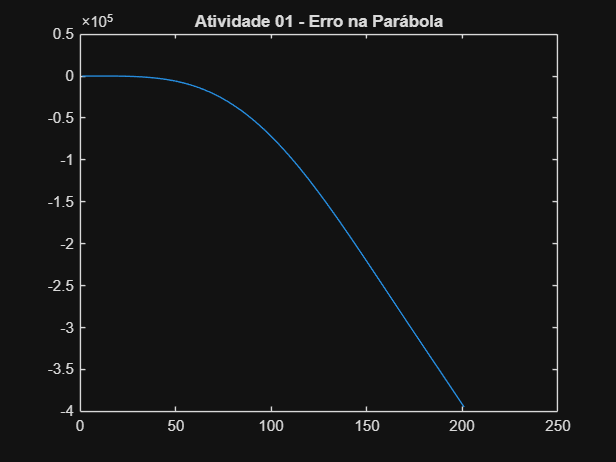

figure(5)
plot(r-y_parab) %mostra sinal de erro
title('Atividade 01 - Erro na Parábola')

**Resposta: **Analisando os gráficos, concluímos que o a função de transferência é do tipo 0, uma vez que os gráficos de rampa e parábola apresentam erros não nulos. 

## Atividade 02 

clear all;
close all;
clc;

Especificações solicitadas para projeto:

Mp = 0.15;
tp_max = 0.5;
ts_max = 3;
xi_min = abs(log(Mp)/sqrt(pi^2 + log(Mp)^2)); % sobressinal
wd_min = pi/tp_max; % pico 
wd_max = 6*pi;
sigma_min = 4/ts_max; % acomodação
T = 0.25;
dw = 0.001;

Subplot 1 - Plano S

% Borda de xi = xi_min (vermelho)
wn = 0:dw:4.5*pi;
xi = xi_min;
s_xi = -xi*wn+1j*wn*sqrt(1-xi^2);

% Borda de sigma = sigma_min (azul)
wd = 0:dw:4*pi; % varre imag
s_sig = -sigma_min+1j*wd;

% Borda de wd = wd_min (verde)
sigma = 0:0.001:30; % varre real
s_wd = -sigma+1j*wd_min;
s_wdmax = -sigma+1j*wd_max;

figure(2)
subplot(131)
hold on
line([-2.2*pi 2.2*pi],[0 0],'linewidth',2,'color','black') % eixo-real
line([0 0],[-2.2*pi 2.2*pi],'linewidth',2,'color','black') % eixo−imag
sgrid

plot(real(s_xi),imag(s_xi),'LineWidth',2,'Color','red')
plot(real(s_xi),-imag(s_xi),'LineWidth',2,'Color','red')

plot(real(s_sig),imag(s_sig),'LineWidth',2,'Color','blue')
plot(real(s_sig),-imag(s_sig),'LineWidth',2,'Color','blue')

plot(real(s_wd),imag(s_wd),'LineWidth',2,'Color','green')
plot(real(s_wd),-imag(s_wd),'LineWidth',2,'Color','green')

plot(real(s_wdmax),imag(s_wdmax),'LineWidth',2,'Color','green')
plot(real(s_wdmax),-imag(s_wdmax),'LineWidth',2,'Color','green')

xlim([-8*pi 8*pi]); 
ylim([-8*pi 8*pi]);

Subplot 2 - Plano Z

xi_min = 0.5169

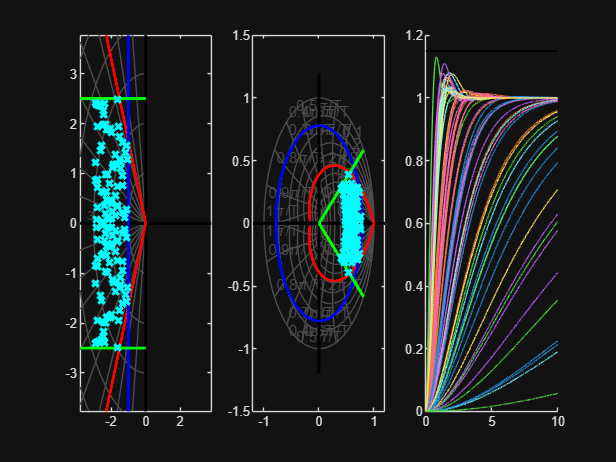

subplot(132)
hold on
% Mapeamento exato z = e^{sT} das três bordas
z_xi = exp(s_xi*T);
z_sig = exp(s_sig*T);
z_wd = exp(s_wd*T);
z_wdmax = exp(s_wdmax*T);

line([-1.2 1.2],[0 0],'linewidth',2,'color','black') % eixo−real
line([0 0],[-1.2 1.2],'linewidth',2,'color','black') % eixo−imag

plot(real(z_xi),imag(z_xi),'LineWidth',2,'Color','red')
plot(real(z_xi),-imag(z_xi),'LineWidth',2,'Color','red')
plot(real(z_sig),imag(z_sig),'LineWidth',2,'Color','blue')
plot(real(z_sig),-imag(z_sig),'LineWidth',2,'Color','blue')
plot(real(z_wd),imag(z_wd),'LineWidth',2,'Color','green')
plot(real(z_wd),-imag(z_wd),'LineWidth',2,'Color','green')
plot(real(z_wdmax),imag(z_wdmax),'LineWidth',2,'Color','green')
plot(real(z_wdmax),-imag(z_wdmax),'LineWidth',2,'Color','green')
zgrid

subplot(133)
hold on
% Define limite de sobressinal de 15%
line([0 10],[1+Mp 1+Mp],'linestyle','--','color','black')
% Define limite de tp = 0.5s
line([0.5 0.5],[0 1+Mp],'linestyle','--','Color','black','linewidth',1.5)

for N=1:100
    wd = wd_min + (wd_max - wd_min)*rand;
    xi = xi_min + (0.95 - xi_min)*rand;
    wn = wd/(sqrt(1-xi^2));
    sigma = xi * wn;

    % Checagem de factibilidade
    if (xi >= xi_min) && (wd >= wd_min) && (wd <= wd_max) && (sigma >= sigma_min)
        figure(2)

    subplot(131)
    s = -sigma+1j*wd;
    plot(real(s),imag(s),'x','Color','c','LineWidth',2)
    plot(real(s),-imag(s),'x','Color','c','LineWidth',2)

    subplot(132)
    z = exp(s*T);
    plot(real(z),imag(z),'x','Color','c','LineWidth',2)
    plot(real(z),-imag(z),'x','Color','c','LineWidth',2)

    % Resposta ao degrau do modelo de 2ª ordem
    subplot(133)
    G = tf([wn^2],[1 2*xi*wn wn^2]);
    t = 0:0.001:10;
    y = step(G,t);
    plot(t,y)
    drawnow
    xlim([0 3]);
    end

end

## Atividade 03 - Controlador por Emulação

close all
clear all
clc
%% Definindo os parâmetros do sistema:
Mp=0.12;
tp=2;
s=tf('s');
G=1/(s*(s+0.5))


G =
 
       1
  -----------
  s^2 + 0.5 s
 
Continuous-time transfer function.


%%
xi=abs(abs(log(Mp)/sqrt(pi^2+log(Mp)^2)))

xi = 0.5594

wd=pi/tp

wd = 1.5708

wn=wd/sqrt(1-xi^2)

wn = 1.8951

Td=2*pi/wd

Td = 4

fd=1/Td

fd = 0.2500

fs=10*fd

fs = 2.5000

Ts=1/fs

Ts = 0.4000

sigma=xi*wn

sigma = 1.0601

a=-0.3;
K=wn^2

K = 3.5913

b=-2*sigma

b = -2.1203

%% Tempo continuo
C=zpk(a,b,K)


C =
 
  3.5913 (s+0.3)
  --------------
     (s+2.12)
 
Continuous-time zero/pole/gain model.


figure
rlocus(C*G)
hold on
Gf=C*G/(1+C*G);
p=pole(Gf)

p =   -2.1203 + 0.0000i
   0.0000 + 0.0000i
  -0.5000 + 0.0000i
  -0.2679 + 0.0000i
  -1.1762 + 1.6241i
  -1.1762 - 1.6241i


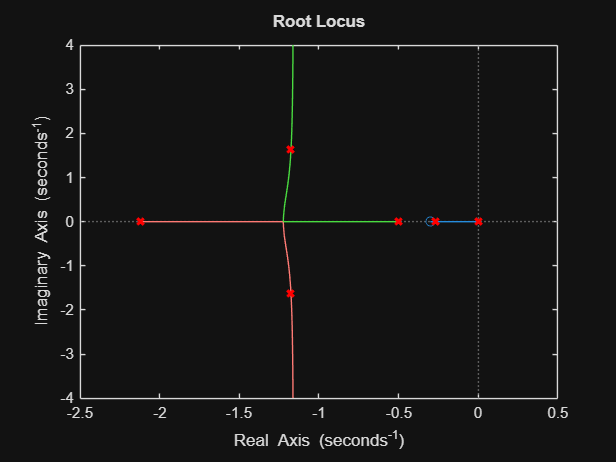

plot(real(p),imag(p),'xr','LineWidth',2)
ylim([-4 4])

info=stepinfo(Gf)

info = struct with fields:
         RiseTime: 1.0666
    TransientTime: 6.7722
     SettlingTime: 6.7722
      SettlingMin: 0.9015
      SettlingMax: 1.0167
        Overshoot: 1.6661
       Undershoot: 0
             Peak: 1.0167
         PeakTime: 2.0360


dt=0.0001;
t=0:dt:10;
y=step(Gf,t);
figure
plot(t,y,'LineWidth',1.5)
hold on
%% Tempo discreto (emulacao)
Ts=[0.2 0.1 0.01];
for i=1:numel(Ts)
    Cd=c2d(C,Ts(i),'matched');
    Gd=c2d(G,Ts(i),'matched');
    Gfd=Cd*Gd/(1+Cd*Gd);
    td=0:Ts(i):10;
    info=stepinfo(Gfd)
    yd=step(Gfd,td);
    stairs(td,yd,'LineWidth',1.5)
end

info = struct with fields:
         RiseTime: 0.8000
    TransientTime: 6.4000
     SettlingTime: 6.4000
      SettlingMin: 0.9041
      SettlingMax: 1.0818
        Overshoot: 8.1828
       Undershoot: 0
             Peak: 1.0818
         PeakTime: 1.8000


info = struct with fields:
         RiseTime: 1
    TransientTime: 6.7000
     SettlingTime: 6.7000
      SettlingMin: 0.9223
      SettlingMax: 1.0453
        Overshoot: 4.5324
       Undershoot: 0
             Peak: 1.0453
         PeakTime: 1.9000


info = struct with fields:
         RiseTime: 1.0500
    TransientTime: 6.7600
     SettlingTime: 6.7600
      SettlingMin: 0.9002
      SettlingMax: 1.0193
        Overshoot: 1.9328
       Undershoot: 0
             Peak: 1.0193
         PeakTime: 1.9900


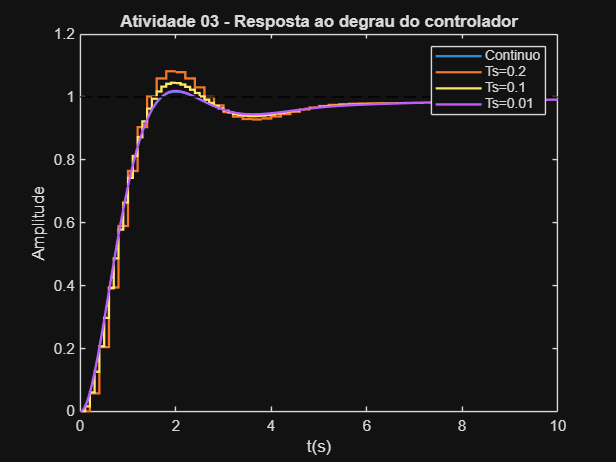

line([0 max(t)],[1 1],'color','black','linestyle','--')
legend('Continuo','Ts=0.2','Ts=0.1','Ts=0.01')
title('Atividade 03 - Resposta ao degrau do controlador')
xlabel('t(s)')
ylabel('Amplitude')

**Resposta:** Em relação ao tempo discreto e o tempo contínuo, pode-se concluir que quanto menor o tempo de amostragem do sistema, mais o mesmo se aproxima do sinal contínuo. 

## Atividade 04

close all;
clear all;
clc;

Parâmetros de Projeto + Definição da Função de Transferência:

Mp=0.12;
tp=2;
s=tf('s');
G=1/(s*(s+0.5))


G =
 
       1
  -----------
  s^2 + 0.5 s
 
Continuous-time transfer function.


Calculando Xi, Wd e Wn

xi=abs(abs(log(Mp)/sqrt(pi^2+log(Mp)^2)))

xi = 0.5594

wd=pi/tp

wd = 1.5708

wn=wd/sqrt(1-xi^2)

wn = 1.8951

Td=2*pi/wd

Td = 4

fd=1/Td

fd = 0.2500

fs=10*fd

fs = 2.5000

Ts=1/fs

Ts = 0.4000

sigma=xi*wn

sigma = 1.0601

a=-0.3;
K=wn^2

K = 3.5913

b=-2*sigma

b = -2.1203

Tempo discreto

Ts=0.2;
Cd=zpk(0.9418,0.3067,9.2294,Ts)


Cd =
 
  9.2294 (z-0.9418)
  -----------------
     (z-0.3067)
 
Sample time: 0.2 seconds
Discrete-time zero/pole/gain model.


Gd=c2d(G,Ts,'zoh');
Gfd=Cd*Gd/(1+Cd*Gd);
td=0:Ts:10;
info=stepinfo(Gfd)

info = struct with fields:
         RiseTime: 0.6000
    TransientTime: 5
     SettlingTime: 5
      SettlingMin: 0.9322
      SettlingMax: 1.0844
        Overshoot: 8.4379
       Undershoot: 0
             Peak: 1.0844
         PeakTime: 1


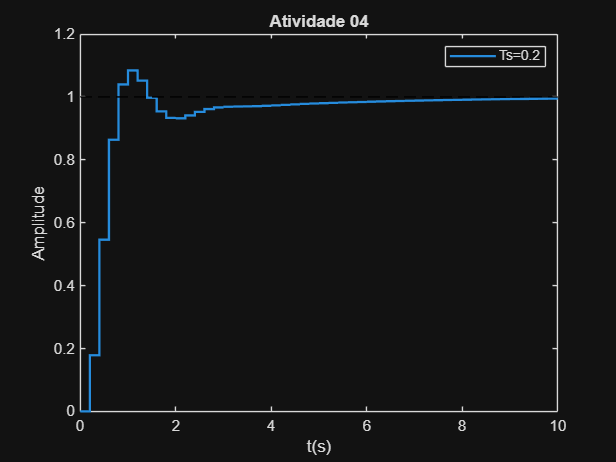

yd=step(Gfd,td);
stairs(td,yd,'LineWidth',1.5)
line([0 max(td)],[1 1],'color','black','linestyle','--')
legend('Ts=0.2')
title('Atividade 04')
xlabel('t(s)')
ylabel('Amplitude')

## Atividade 05 - Projeto do Controlador

Especificações do Projeto: 

Mp=0.10;
tp=2;

Definindo a função de transferência: 

s=tf('s');
G=15/((s+2)*(s+4));

Calculando Xi e Wn:

xi=abs(log(Mp)/(sqrt(pi^2+log(Mp)^2)));
wn=3/(xi*tp);

Determinando os polos dominantes:

% Determinção dos polos dominantes
s1=-xi*wn+1i*wn*sqrt(1-xi^2);
s2=-xi*wn-1i*wn*sqrt(1-xi^2);

a = 2*(3-xi*wn);
Kp=(wn^2+2*xi*wn*a-8)/15;
Ti=15*Kp/(a*wn^2);

Cs=Kp*(1+1/(s*Ti));
Cd=c2d(Cs, Ts, 'tustin');
Gd=c2d(G, Ts, 'tustin');

Tempo Discreto:

dt = 0.001;
t=0:dt:10;
td=0:Ts:10;
Gf = (G*Cs)/(1+G*Cs);
Gdf = (Gd*Cd)/(1+Gd*Cd);
yu = step(Gf, t);
yud = step(Gdf, td);
figure
plot(t, yu, DisplayName='Tempo contínuo')
hold on
stairs(td, yud, DisplayName='Tempo discreto')
overshoot=stepinfo(Gdf).Overshoot

overshoot = 12.5859

temp_acom=stepinfo(Gdf).SettlingTime

temp_acom = 2.4000

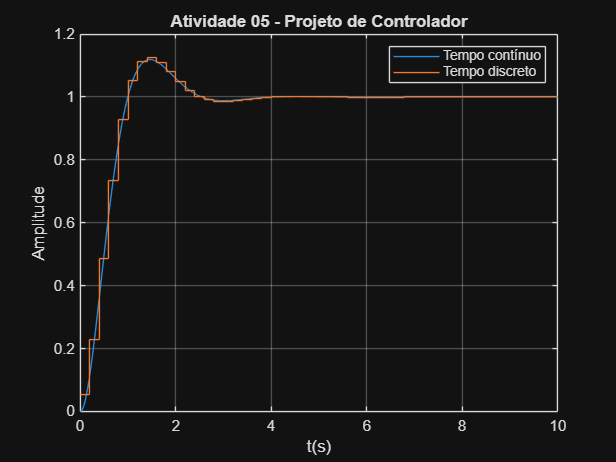

title('Atividade 05 - Projeto de Controlador')
xlabel('t(s)')
ylabel('Amplitude')
legend()
grid on